Effect of GA options

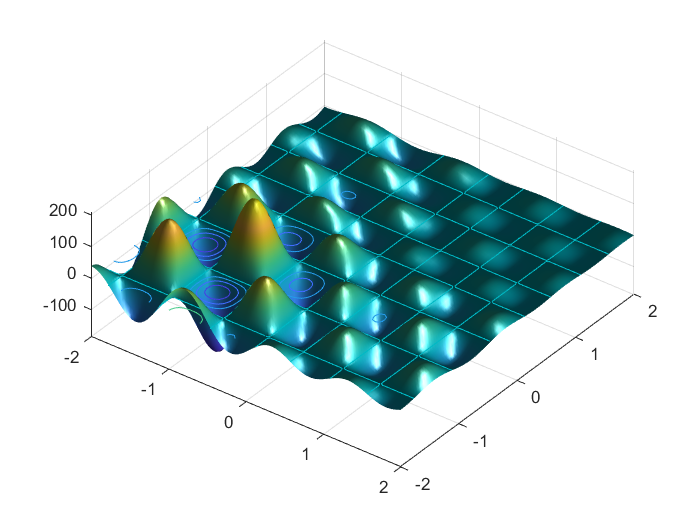

plotobjective (@shufcn, [-2 2,; -2 2])

tic

FitnessFcn = @shufcn ;
nvars = 2 ;
rng default % for reproducibility

[x, Fval, Exitflag, Output] = ga (FitnessFcn, nvars);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.



fprintf ('The number of generations was : %d\n', Output.generations)

The number of generations was : 124


fprintf ('The number of function evaluations was : %d\n', Output.funccount)

The number of function evaluations was : 5881


fprintf ('The best function value found was : %g\n', Fval)

The best function value found was : -186.199



toc

Elapsed time is 0.923413 seconds.


Plotting performance

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


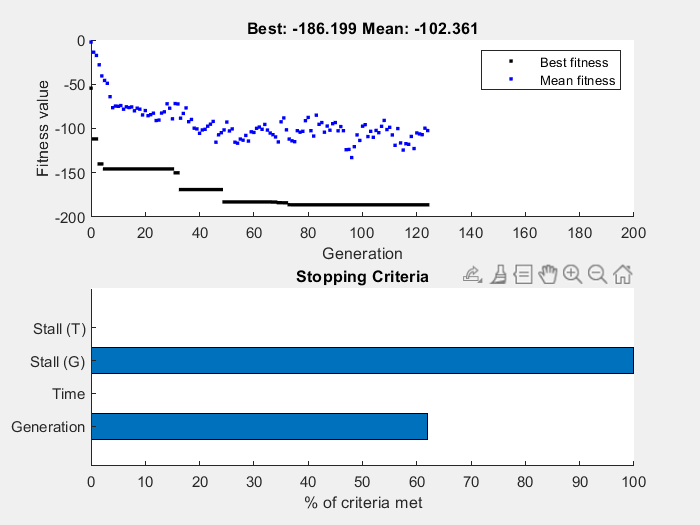

tic

rng default % for reproducibility
FitnessFcn = @shufcn ;
nvars = 2 ;
options = optimoptions (@ga, 'PlotFcn', {@gaplotbestf, @gaplotstopping}) ;

[x, Fval, Exitflag, Output] = ga (FitnessFcn, nvars, [], [], [], [], [], [], [], [], options);


fprintf ('The number of generations was : %d\n', Output.generations)

The number of generations was : 124


fprintf ('The number of function evaluations was : %d\n', Output.funccount)

The number of function evaluations was : 5881


fprintf ('The best function value found was : %g\n', Fval)

The best function value found was : -186.199



toc

Elapsed time is 9.471681 seconds.


Modifiy the options

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


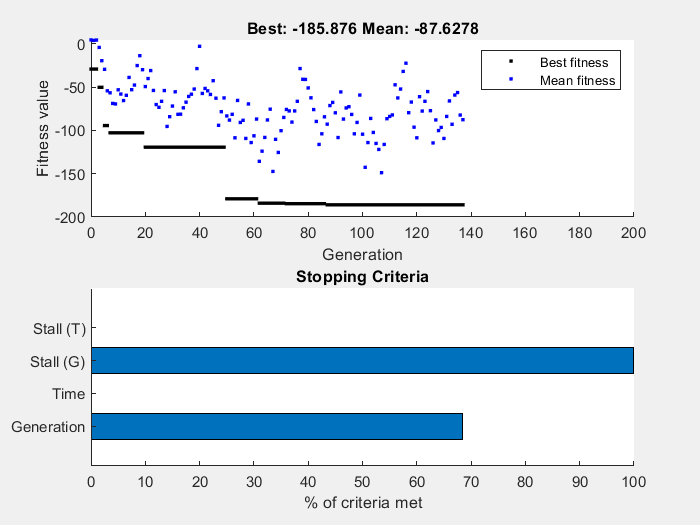


tic

rng default % for reproducibility
FitnessFcn = @shufcn ;
nvars = 2 ;
options = optimoptions (@ga, 'PlotFcn', {@gaplotbestf, @gaplotstopping}) ;
options.PopulationSize = 10 ;
options.InitialPopulationRange = [-1 0; 1 2] ;
[x, Fval, Exitflag, Output] = ga (FitnessFcn, nvars, [], [], [], [], [], [], [], [], options);


fprintf ('The number of generations was : %d\n', Output.generations)

The number of generations was : 137


fprintf ('The number of function evaluations was : %d\n', Output.funccount)

The number of function evaluations was : 1244


fprintf ('The best function value found was : %g\n', Fval)

The best function value found was : -185.876



toc

Elapsed time is 4.337935 seconds.
